clear all
close all
clc

### Constraints

WIN = 50; %window size for cross-correlogram [ms]
DELTA = 1; % bin width for histogram [ms]--> excitatory?
NPAR = 102;
MAX = 200000;

### Plot histogram

T = 5400; %duration of recording [s]
cc_list = linear_crossCorrelogram('cell9.txt','cell4.txt',T,WIN,DELTA);

n_pre: 11519
n_post: 10011


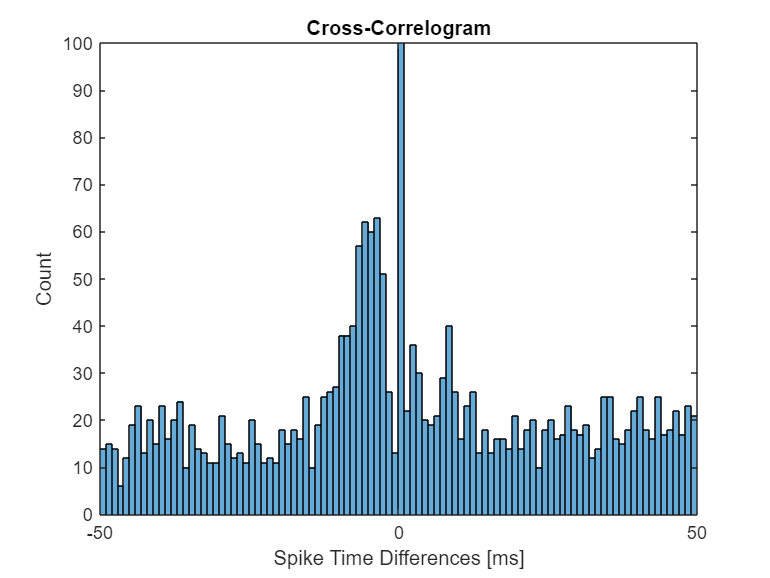

bin_width = DELTA;
bin_num = 2* WIN / bin_width;

histogram(cc_list{1},linspace(-WIN,WIN,bin_num+1)); % bisogna specificare il type of normalization???
xlim([-WIN,WIN]);
ylim([0 bin_num]);
xlabel('Spike Time Differences [ms]');
ylabel('Count');
title('Cross-Correlogram');